Experimento 1

ResultadosIA

ResultadosIA = 10×3 table
     VarName1     MoverPrincipio    MoverFinal
    __________    ______________    __________

         10323        10039            9919   
         72718        10772           10707   
     1.109e+05        11362           10876   
         31416        10868           10614   
      1.51e+05        10382           10424   
     1.009e+05        11318           11202   
     2.012e+05        10977           10757   
         20902        11017           10913   
    5.1354e+07        11114           10521   
    4.8791e+05        11297           11020   


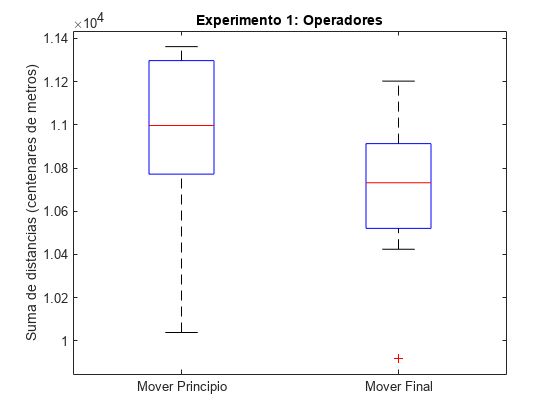


boxplot([ResultadosIA.MoverPrincipio ResultadosIA.MoverFinal], 'Labels',{'Mover Principio','Mover Final'})
title("Experimento 1: Operadores")
ylabel("Suma de distancias (centenares de metros)")



[h, p] = ttest(ResultadosIA.MoverPrincipio, ResultadosIA.MoverFinal)

h = 1

p = 0.0061

Experimento 2: Greedy vs Random

Experimento2 = ResultadosIA4S1

Experimento2 = 10×5 table
     VarName1     GREEDY    RANDOMMediaDe5    TiempoGreedy    TiempoRandomMediaDe5
    __________    ______    ______________    ____________    ____________________

         10324    10656         10805            10886               10692        
         72719    10452         10572             7940                9301        
     1.109e+05    10667         10598             9921               11070        
         31417    10293         10272             8603               11636        
      1.51e+05    10903         11080             9342                9903        
     1.009e+05    10555         10769             9470               10618        
     2.012e+05    10834         11280            10613                9969        
         20903    10970         11041             9101  

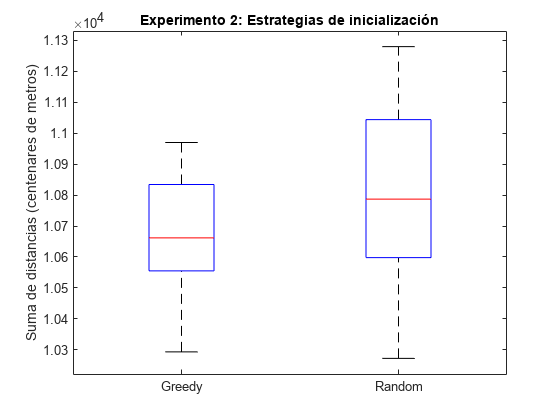


boxplot([Experimento2.GREEDY Experimento2.RANDOMMediaDe5], 'Labels',{'Greedy','Random'})
title("Experimento 2: Estrategias de inicialización")
ylabel("Suma de distancias (centenares de metros)")

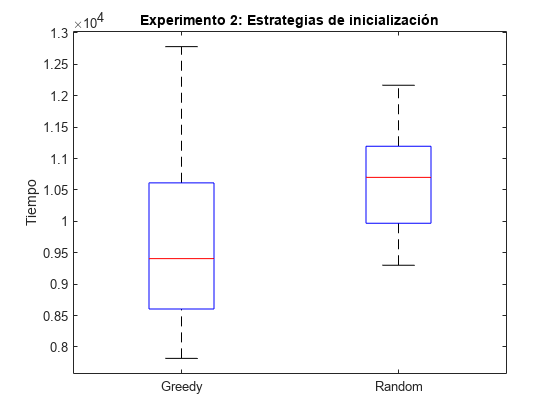


boxplot([Experimento2.TiempoGreedy Experimento2.TiempoRandomMediaDe5], 'Labels',{'Greedy','Random'})
title("Experimento 2: Estrategias de inicialización")
ylabel("Tiempo")


[h,p,~,stats] = ttest(Experimento2.GREEDY, Experimento2.RANDOMMediaDe5,"Tail","right")

h = 0

p = 0.9839

stats = struct with fields:
    tstat: -2.5293
       df: 9
       sd: 180.1656


[h,p,~,stats] = ttest(Experimento2.TiempoGreedy, Experimento2.TiempoRandomMediaDe5,"Tail","right")

h = 0

p = 0.9847

stats = struct with fields:
    tstat: -2.5615
       df: 9
       sd: 1.3311e+03


Experimento 3: Lambda-Experimentación

Experimento3 

Experimento3 = 10×4 table
       Seed       VarName2    VarName3    VarName4
    __________    ________    ________    ________

         20646     10548       10576       10872  
    1.4544e+05     10702       10702       10718  
     2.218e+05     10630       10630       10630  
         62832     10327       10516       10430  
      3.02e+05     10634       10634       10607  
     2.018e+05     10622       10377       10781  
     4.024e+05     10306       10298       10630  
         41804      9962        9962        9962  
    1.0271e+08     10795       10777       10867  
    9.7582e+05     10369       10369       10429  


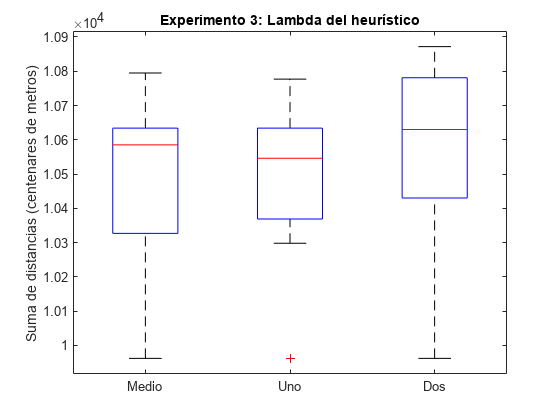


boxplot([Experimento3.VarName2, Experimento3.VarName3, Experimento3.VarName4], 'Labels',{'Medio','Uno', 'Dos'})
title("Experimento 3: Lambda del heurístico")
ylabel("Suma de distancias (centenares de metros)")


[h1,p1,~,stats] = ttest(Experimento3.VarName2, Experimento3.VarName3)

h1 = 0

p1 = 0.8727

stats = struct with fields:
    tstat: 0.1648
       df: 9
       sd: 103.6160


[h2,p2,~,stats] = ttest(Experimento3.VarName2, Experimento3.VarName4)

h2 = 1

p2 = 0.0322

stats = struct with fields:
    tstat: -2.5312
       df: 9
       sd: 128.8043


[h3,p3,~,stats] = ttest(Experimento3.VarName3, Experimento3.VarName4)

h3 = 0

p3 = 0.0759

stats = struct with fields:
    tstat: -2.0055
       df: 9
       sd: 171.0797


Experimento 4: Guerra de los Heurísticos

Experimento4 = ResultadosIA7S3

Experimento4 = 10×4 table
       Seed       SumaDistancia    Entropia    Lamda1
    __________    _____________    ________    ______

          5161        10752         10791      10813 
         36359         9926         10471       9904 
         55450        10738         11125      10692 
         15708        11133         11196      10979 
         75501        10759         10961      10617 
         50451        10348         10725      10288 
     1.006e+05        10378         10903      10792 
         10451        10220         10330      10235 
    2.5677e+07        10707         10986      10781 
    2.4396e+05        11162         11724      11280 


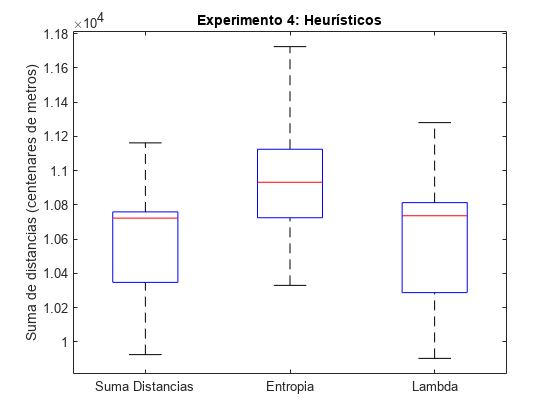


boxplot([Experimento4.SumaDistancia, Experimento4.Entropia, Experimento4.Lamda1], 'Labels',{'Suma Distancias','Entropia', 'Lambda'})
title("Experimento 4: Heurísticos")
ylabel("Suma de distancias (centenares de metros)")


[h1,p1,~,stats] = ttest(Experimento4.SumaDistancia, Experimento4.Entropia)

h1 = 1

p1 = 8.8633e-04

stats = struct with fields:
    tstat: -4.8677
       df: 9
       sd: 200.6752


[h2,p2,~,stats] = ttest(Experimento4.Entropia, Experimento4.Lamda1)

h2 = 1

p2 = 0.0011

stats = struct with fields:
    tstat: 4.7117
       df: 9
       sd: 190.0020


[h3,p3,~,stats] = ttest(Experimento4.SumaDistancia, Experimento4.Lamda1, "Tail", "Right")

h3 = 0

p3 = 0.3140

stats = struct with fields:
    tstat: -0.5015
       df: 9
       sd: 162.6740


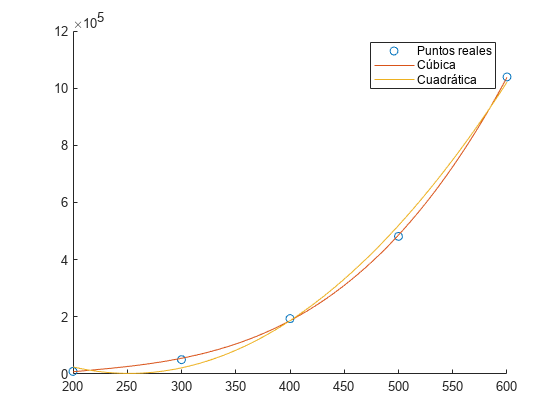



x = [200:100:600];
y = [9147.1, 50254.5, 193824.2, 481523.8, 1039274.25];
g = polyfit(x, y, 2);
g2 = polyfit(x, y, 3);
%f = fit(x', y', "exp1");
x2 = linspace(200, 600, 1000);
y2 = polyval(g, x2);
y3 = polyval(g2, x2);
scatter(x, y);
hold on
plot(x2, y3, x2, y2);
legend("Puntos reales", "Cúbica", "Cuadrática");
hold off

%plot(f);